## Tandhjul

### Opgave

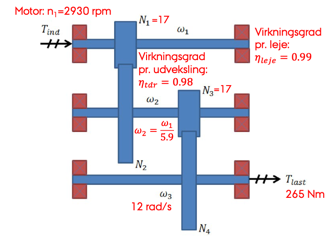

Bestem:

**a) Motormomentet**

Vi har at $P = T\omega$. 

Altså findes output-effekten som

T_last = 265;
omega_3 = 12;

P_out = T_last * omega_3;

Denne effekt er formindsket af $\eta_{tdr} = 0.98$ for de to udvekslinger og $\eta_{leje} = 0.99$ for de 2 aksler på hvert af de tre lejer. Altså er den totale virkningsgrad:

eta_leje = 0.99;
eta_tdr = 0.98;

eta = (eta_leje^2)^3 * eta_tdr^2;

Dermed er inputeffekten:

P_in = P_out/eta;

Dermed er motormomentet:

n_1 = 2930; %rpm
omega_1 = n_1 * 2*pi/60;

T_1 = P_in/omega_1;

fprintf("Dermed er motormomentet T = %.2f Nm\n", T_1);

Dermed er motormomentet T = 11.46 Nm


b) Motoreffekten

Motoreffekten er ovenfor fundet som `P_in:`

fprintf("Motoreffekten er P_in = %.2f W\n", P_in);

Motoreffekten er P_in = 3516.93 W


c) $N_2$ og $N_4$. Tolerancerne for $\omega_3$ er $\pm 1\%$.

Mellem to tandhjul $a$ og $b$ har vi generelt


$$\omega_a N_a = \omega_b N_b$$


Altså kan $N_2$ findes som


$$N_2 = \frac{\omega_1}{\omega_2} N_1$$


omega_2 = omega_1/5.9;
N_1 = 17;

N_2 = round(omega_1/omega_2 * N_1);

fprintf("Altså skal tandhjul 2 have %.0f tænder\n", N_2);

Altså skal tandhjul 2 have 100 tænder


Samme metode udføres for tandhjul 4:

N_3 = 17;

N_4 = round(omega_2/omega_3 * N_3);

fprintf("Altså skal tandhjul 4 have %.0f tænder\n", N_4);

Altså skal tandhjul 4 have 74 tænder


Vi tjekker nu at $\omega_3$ rammer indenfor tolerancen ved at bruge den kendte $\omega_1$ og gearforholdene


$$\omega_3 =\omega_1 \frac{N_1 N_3 \;}{N_2 N_4 }$$


omega_3 = omega_1 * N_1 * N_3 / (N_2 * N_4);

afvigelseProcent = (omega_3 - 12)/12 *100; %original omega_3 is redefined so we use 12 manually

ok = NaN;

if afvigelseProcent < 1
    ok = true;
else
    ok = false;
end

fprintf("Den egentlige rotationshastighed ved lasten er %.2f rad/s\nDette afviger med %.2f%% ift. den angivne værdi på 12 rad/s", omega_3, afvigelseProcent);

Den egentlige rotationshastighed ved lasten er 11.98 rad/s
Dette afviger med -0.14% ift. den angivne værdi på 12 rad/s

if ok
  fprintf("Dette er inden for grænsen på 1%%");
else
  fprintf("Dette er IKKE inden for grænsen på 1%%");
end

Dette er inden for grænsen på 1%

d) Akslernes diametre på baggrund af torsionsmomenterne. $\tau_{till} = 28 MPa$.

Vi nu genbruge $P = T\omega$. 

P_3 = P_out/eta_leje^2;
P_2 = P_3/(eta_leje^2 * eta_tdr);

T_3 = P_3/omega_3;
T_2 = P_2/omega_2;

For en massiv cirkulær aksel har vi

$\tau_{max} = \frac{Tr}{J} = \frac{16 T}{\pi d^3}$ => $d={\left(\frac{16\;T}{\pi \;\tau_{\textrm{till}} }\right)}^{\frac{1}{3}}$

Altså kan vi finde de påkrævede diametre som:

T_list = [T_1, T_2, T_3];

tau_till = 28e6;

d = (16*T_list/(pi*tau_till)).^(1/3);
d_mm = 1e3*d;

for i = 1:numel(T_list)
    fprintf("Aksel %d: T = %.2f Nm -> d_min = %.2f mm\n", i, T_list(i), d_mm(i));
end

Aksel 1: T = 11.46 Nm -> d_min = 12.77 mm
Aksel 2: T = 64.96 Nm -> d_min = 22.78 mm
Aksel 3: T = 270.77 Nm -> d_min = 36.66 mm


e) Tandhjulenes delecirkeldiameter. Moduler er $m_1 = m_2 = 2 mm$. $m_3 = m_4 = 3 mm$.

Vi har at delecirkeldiameteren $d$ er givet som:


$$d = N \cdot m$$


Altså:

N = [N_1, N_2, N_3, N_4];

m = [2, 2, 3, 3]; %mm

d_mm = m .* N;

fprintf("d_1=%.1f mm,\nd_2=%.1f mm,\nd_3=%.1f mm,\nd_4=%.1f mm.", d_mm(1), d_mm(2), d_mm(3), d_mm(4));

d_1=34.0 mm,
d_2=200.0 mm,
d_3=51.0 mm,
d_4=222.0 mm.

f) Indgrebsgrad

eps12 = indgrebsgrad(2, 17, 100);
eps34 = indgrebsgrad(3,17,74);

fprintf("Indgrebsgraden mellem tandhjul 1 og 2 er %.2f,\nmellem tandhjul 3 og 4 er den %.2f", eps12, eps34);

Indgrebsgraden mellem tandhjul 1 og 2 er 1.68,
mellem tandhjul 3 og 4 er den 1.67

g) Aksial, tangential og radial kræfter i tandhjulene

For lige fortanding har vi:


$$F_t =2\frac{T}{d}\;\;\;\;\;\;\;\;\;\;F_r =F_t \tan \alpha \;\;\;\;\;\;\;\;\;\;\;F_a =0$$


Generelt er $\alpha = 20^\circ$. Altså får vi:

d_m = d_mm / 1000;
alpha = 20;

F_t12 = 2 * T_1/d_m(1);
F_r12 = F_t12 * tand(alpha);
F_a12 = 0;

F_t34 = 2 * T_2/d_m(3);
F_r34 = F_t34 * tand(alpha);
F_a34 = 0;

fprintf("Indgreb 1 (1-2): Ft = %.1f N, Fr = %.1f N, Fa = %.1f N\n", F_t12, F_r12, F_a12);

Indgreb 1 (1-2): Ft = 674.2 N, Fr = 245.4 N, Fa = 0.0 N


fprintf("Indgreb 2 (3-4): Ft = %.1f N, Fr = %.1f N, Fa = %.1f N\n", F_t34, F_r34, F_a34);

Indgreb 2 (3-4): Ft = 2547.3 N, Fr = 927.1 N, Fa = 0.0 N


h) Tandfodsspændinger for tandhjulene. Tandbredde $5\pi m_i$. Kvalitetstal $Q_v = 5$.

Spændingerne i tandfoden $\sigma$ er:


$$\sigma =K_v \;\frac{W_t }{b\cdot m\cdot Y}$$


Hvor $W_t$ er tangentialkraften, $b$ er tandbredden, $m$ er modulet, $Y$ er Lewis formfaktoren og $K_v$ er den dynamiske faktor.

Her er $Y = \frac{1}{K_{\epsilon} K_F}$


$$K_{\epsilon \;} =\frac{1}{m_c }$$



$$K_F =2\ldotp 2+3\ldotp 1e^{-\frac{N}{14}}$$



$$K_v ={\left(\frac{A+\sqrt{\;200\cdot V}}{A}\right)}^B$$



$$V=\frac{d}{2}\omega \;$$



$$A=50+56\left(1-B\right)$$



$$B=0\ldotp 25\cdot {\left(12-Q_v \right)}^{\frac{2}{3}}$$


Q_v = 5;

m12 = 2;
b12 = 5 * pi * m12;

m34 = 3;
b34 = 5 * pi * m34;

s1 = tandfodspaending(F_t12, b12, m12, eps12, N_1, d_m(1), omega_1, Q_v);
s2 = tandfodspaending(F_t12, b12, m12, eps12, N_2, d_m(1), omega_1, Q_v);
s3 = tandfodspaending(F_t34, b34, m34, eps34, N_3, d_m(3), omega_2, Q_v);
s4 = tandfodspaending(F_t34, b34, m34, eps34, N_4, d_m(3), omega_2, Q_v);


fprintf("sigma_1 = %.1f MPa\n", s1);

sigma_1 = 30.4 MPa


fprintf("sigma_2 = %.1f MPa\n", s2);

sigma_2 = 21.5 MPa


fprintf("sigma_3 = %.1f MPa\n", s3);

sigma_3 = 42.8 MPa


fprintf("sigma_4 = %.1f MPa\n", s4);

sigma_4 = 30.4 MPa
